## Include Parameters or Data

Numberofvariables=6;
lowerbounds=[0 0.05 0.05 0 0 0];
upperbounds=[1 1 1 1 1 1];

## Optimize Live Editor Task

Optimization terminated: maximum number of generations exceeded.


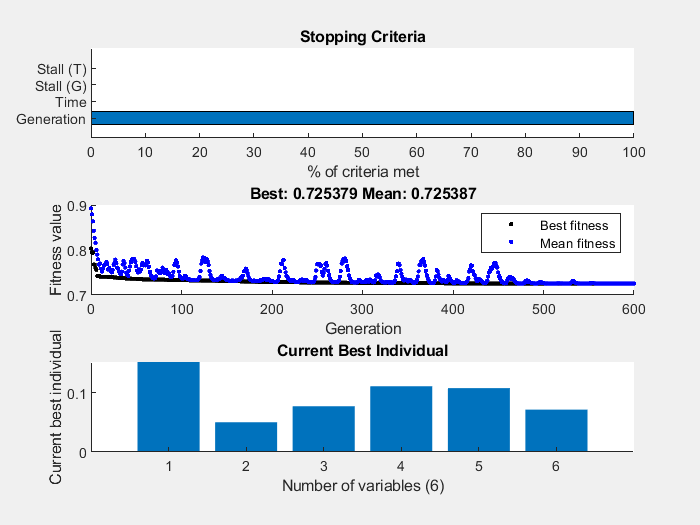

% Set nondefault solver options
options = optimoptions("ga","PopulationSize",200,"MaxGenerations",600,...
    "MaxStallGenerations",500,"MaxStallTime",200,"PlotFcn",["gaplotstopping",...
    "gaplotbestf","gaplotbestindiv"]);

% Solve
[solution,objectiveValue] = ga(@CalcAvGamma4,Numberofvariables,[],[],[],[],...
    lowerbounds,upperbounds,[],[],options);


% Clear variables
clearvars options

## Results

p=solution

p =     0.1514    0.0500    0.0770    0.1107    0.1075    0.0713
